# 交互教学 04：储能选址定容与交流潮流验证

本节采用无光伏注入的纯负荷馈线。储能按五种功率/能量配置方案选择，采用大M法和 LinDistFlow 建立 MILP，再代入交流潮流计算。

## 使用方法

先将 MATLAB 当前文件夹切换到 interactive。首次点击“全部运行”。修改计算参数后重新运行；查看时段、支路或节点的滑块只更新所在节的图形。

lesson = ess_live_setup();
export_figures = true;

## 个人学号与本次计算条件

修改学号后重新运行后续各节。算例、负荷系数和候选节点沿用课程统一规则。

Stu_ID = 242400031;
XY=mod(Stu_ID,100);
X_digit=floor(XY/10); Y_digit=mod(XY,10);
alpha=1+0.002*XY;
if ismember(Y_digit,[0 1 2 3])
    case_name='case_nongcun';
elseif ismember(Y_digit,[4 5 6])
    case_name='case_chengshi_A';
else
    case_name='case_kaifaqu_A';
end
if ismember(X_digit,[0 1 2])
    study_buses=[4 9 14]; model_type='A';
elseif ismember(X_digit,[3 4 5])
    study_buses=[5 11 16]; model_type='B';
else
    study_buses=[6 13 17]; model_type='C';
end
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T; dt=1;
load_curve_pu=profiles.load_curve_pu; pv_curve_pu=profiles.pv_curve_pu;
price_MWh=profiles.price_MWh; price_kWh=profiles.price_kWh;
disp(table(Stu_ID,string(case_name),alpha,string(model_type),string(mat2str(study_buses)),...
    'VariableNames',{'StudentID','Case','LoadMultiplier','Objective','StudyNodes'}));

    StudentID         Case         LoadMultiplier    Objective    StudyNodes 
    _________    ______________    ______________    _________    ___________

    2.424e+08    "case_nongcun"        1.062            "B"       "[5 11 16]"



mpc=loadcase(case_name);
cand_buses=study_buses;N_cand=numel(cand_buses);
yalmip('clear');

## 大M法：辅助变量与配置选择

四条约束利用荷电状态上下界构造。分别选择 w=0 和 w=1，观察允许的辅助变量是否为 0 和 SoC。


$$\delta=\mathrm{SoC}\,w$$


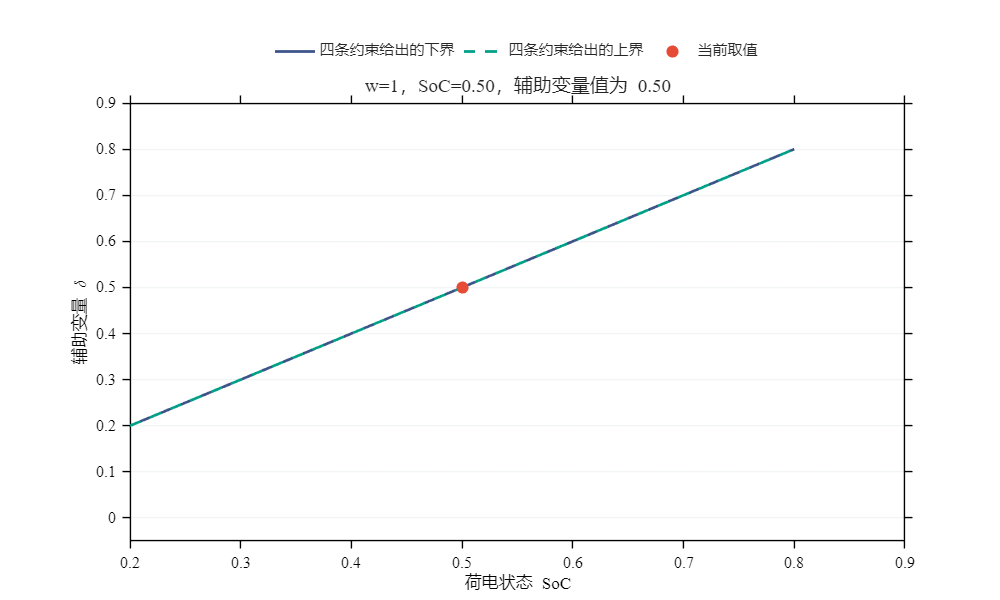

demo_soc = 0.5;
demo_w = 1;
fig_bigm=ess_live_view('bigm',demo_soc,demo_w);

Delta_Lower=max(0.2*demo_w,demo_soc-0.8*(1-demo_w));
Delta_Upper=min(0.8*demo_w,demo_soc-0.2*(1-demo_w));
disp(table(demo_soc,demo_w,Delta_Lower,Delta_Upper));

    demo_soc    demo_w    Delta_Lower    Delta_Upper
    ________    ______    ___________    ___________

      0.5         1           0.5            0.5    



## 配置方案与经济参数

五种配置方案按相同档位选择功率与能量容量。初末荷电状态为 0.50，运行范围为 0.20 至 0.80。

P_opt_MW  = [1, 2, 3, 4, 5];
E_opt_MWh = [1, 2, 3, 4, 5];
K = length(E_opt_MWh);
eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;
c_P    = 0.08 * 1e6;
c_E    = 0.55 * 1e6;
c_om   = 200 * 1e3;
Y_life = 20;
d_rate = 0.05;
CRF    = (d_rate * (1 + d_rate)^Y_life) / ((1 + d_rate)^Y_life - 1);
D_days = 365;
V_min_Lin = 0.960;
V_max_Lin = 1.050;

## 电压裕度与投资费用试验

默认参数与课程参考模型一致。修改线性模型电压下限或能量投资费用倍率后，重新运行后续模型及交流潮流计算。

V_min_Lin = 0.96;
energy_cost_multiplier = 1;
c_E=0.55*1e6*energy_cost_multiplier;

## 构造逐时负荷与网络参数

网络采用标幺值，储能充放电功率采用 MW。

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
fbus  = mpc.branch(:, 1);
tbus  = mpc.branch(:, 2);
r_br  = mpc.branch(:, 3);
x_br  = mpc.branch(:, 4);
Pd_pu = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';

## 声明选址、配置与运行变量

z 表示建站，w 表示配置选择，delta 按候选节点、配置方案、时段排列。

z        = binvar(N_cand, 1, 'full');
w        = binvar(N_cand, K, 'full');
SoC      = sdpvar(N_cand, T, 'full');
delta    = sdpvar(N_cand, K, T, 'full');
P_ch_MW  = sdpvar(N_cand, T, 'full');
P_dis_MW = sdpvar(N_cand, T, 'full');
u_ch     = binvar(N_cand, T, 'full');
U_lin     = sdpvar(N_bus, T, 'full');
P_br      = sdpvar(N_br,  T, 'full');
Q_br      = sdpvar(N_br,  T, 'full');
P_grid_pu = sdpvar(1,     T, 'full');
Q_grid_pu = sdpvar(1,     T, 'full');

## 构造配置选择与储能运行约束

逐项对应配置选择、四条大M约束、初末状态及能量平衡。


$$\sum_k E_k^{\mathrm{opt}}(\delta_{i,k,t}-\delta_{i,k,t-1})=(\eta_{\mathrm{ch}}P_{i,t}^{\mathrm{ch}}-P_{i,t}^{\mathrm{dis}}/\eta_{\mathrm{dis}})\Delta t$$


## 大M法的下界与上界（一）

配置未选择时，以下约束使辅助变量为零。


$$\mathrm{SoC}_{\min}w_{i,k}\le\delta_{i,k,t}\le\mathrm{SoC}_{\max}w_{i,k}$$


## 大M法的下界与上界（二）

配置被选择时，以下约束使辅助变量等于荷电状态。


$$\mathrm{SoC}_{i,t}-\mathrm{SoC}_{\max}(1-w_{i,k})\le\delta_{i,k,t}\le\mathrm{SoC}_{i,t}-\mathrm{SoC}_{\min}(1-w_{i,k})$$


Constraints = [];
P_rated     = w * P_opt_MW';
E_rated     = w * E_opt_MWh';
P_rated_MW  = P_rated;
E_rated_MWh = E_rated;
P_max_bound = max(P_opt_MW);
for idx = 1:N_cand
    Constraints = [Constraints, sum(w(idx, :)) == z(idx)];
    Constraints = [Constraints, SoC_min <= SoC(idx, :) <= SoC_max];
    Constraints = [Constraints, SoC(idx, T) == SoC_0];
    Constraints = [Constraints, 0 <= P_ch_MW(idx, :)  <= P_rated_MW(idx)];
    Constraints = [Constraints, 0 <= P_dis_MW(idx, :) <= P_rated_MW(idx)];
    Constraints = [Constraints, P_ch_MW(idx, :)  <= u_ch(idx, :) * P_max_bound];
    Constraints = [Constraints, P_dis_MW(idx, :) <= (1 - u_ch(idx, :)) * P_max_bound];
    for k = 1:K
        d_vec = reshape(delta(idx, k, :), 1, T);
        Constraints = [Constraints, SoC_min * w(idx, k) <= d_vec <= SoC_max * w(idx, k)];
        Constraints = [Constraints, SoC(idx, :) - SoC_max * (1 - w(idx, k)) <= d_vec <= ...
            SoC(idx, :) - SoC_min * (1 - w(idx, k))];
    end
    for t = 1:T
        if t == 1
            E_prev = E_opt_MWh * (SoC_0 * w(idx, :))';
        else
            E_prev = E_opt_MWh * reshape(delta(idx, :, t - 1), K, 1);
        end
        E_curr = E_opt_MWh * reshape(delta(idx, :, t), K, 1);
        Constraints = [Constraints, E_curr - E_prev == ...
            eta_ch * P_ch_MW(idx, t) - P_dis_MW(idx, t) / eta_dis];
    end
end

## 构造 LinDistFlow 与节点电压约束

对照上一讲支路潮流方程，确认模型中省略的支路损耗项。


$$U_{j,t}=U_{i,t}-2(r_{ij}P_{ij,t}+x_{ij}Q_{ij,t})$$


A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br);
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br);
A_cand  = sparse(cand_buses, 1:N_cand, 1, N_bus, N_cand);
A_slack = sparse(1, 1, 1, N_bus, 1);
Constraints = [Constraints, A_to * P_br - A_from * P_br + A_slack * P_grid_pu + ...
    A_cand * ((P_dis_MW - P_ch_MW) / Sbase) == Pd_pu];
Constraints = [Constraints, A_to * Q_br - A_from * Q_br + A_slack * Q_grid_pu == Qd_pu];
Constraints = [Constraints, U_lin(1, :) == 1.0];
Constraints = [Constraints, (V_min_Lin^2) <= U_lin(2:end, :) <= (V_max_Lin^2)];
for b = 1:N_br
    Constraints = [Constraints, U_lin(tbus(b), :) == U_lin(fbus(b), :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :))];
end

## 建立年综合费用并求解

费用包括投资等年值、年运维费用和按典型日折算的年购电费用。

C_inv_ann  = CRF * sum(c_P * P_rated_MW + c_E * E_rated_MWh);
C_om_ann   = sum(c_om * P_rated_MW);
C_grid_ann = D_days * sum((Sbase * P_grid_pu') .* price_MWh);
Objective  = C_inv_ann + C_om_ann + C_grid_ann;
[sol,solver_name,solve_seconds]=ess_live_solve(Constraints,Objective,'MILP');
assert(sol.problem==0,'规划求解失败：%s',yalmiperror(sol.problem));

## 将最优充放电计划代入交流潮流

无储能和配置后方案使用相同负荷。逐时检查交流潮流收敛，再比较节点电压和有功损耗。

V_lin_pu      = sqrt(value(U_lin));
V_ac_base     = zeros(N_bus, T);
V_ac_ess      = zeros(N_bus, T);
Ploss_ac_base = zeros(T, 1);
Ploss_ac_ess  = zeros(T, 1);
P_net_ess_MW  = value(P_dis_MW - P_ch_MW);
mpopt = mpoption('verbose', 0, 'out.all', 0);
for t = 1:T
    mpc_b = mpc;
    mpc_b.bus(:, 3) = Pd_pu(:, t) * Sbase;
    mpc_b.bus(:, 4) = Qd_pu(:, t) * Sbase;
    res_b = runpf(mpc_b, mpopt);
    assert(res_b.success==1,'无储能方案第 %d 时段潮流未收敛。',t);
    V_ac_base(:, t)  = res_b.bus(:, 8);
    Ploss_ac_base(t) = sum(real(get_losses(res_b)));
    mpc_e = mpc_b;
    mpc_e.bus(cand_buses, 3) = mpc_e.bus(cand_buses, 3) - P_net_ess_MW(:, t);
    res_e = runpf(mpc_e, mpopt);
    assert(res_e.success==1,'配置后第 %d 时段潮流未收敛。',t);
    V_ac_ess(:, t)  = res_e.bus(:, 8);
    Ploss_ac_ess(t) = sum(real(get_losses(res_e)));
end
B_loss_ann           = D_days * sum((Ploss_ac_base - Ploss_ac_ess) .* price_MWh);
max_voltage_error_pu = max(max(abs(V_lin_pu - V_ac_ess)));
fprintf('\n================ 第二周：储能选址定容与交流潮流验证报告 ================\n');


================ 第二周：储能选址定容与交流潮流验证报告 ================


for idx = 1:N_cand
    fprintf('候选节点 %2d: 选址状态 z=%d | 额定功率 = %d MW | 额定容量 = %d MWh\n', ...
        cand_buses(idx), round(value(z(idx))), round(value(P_rated_MW(idx))), round(value(E_rated_MWh(idx))));
end

候选节点  5: 选址状态 z=0 | 额定功率 = 0 MW | 额定容量 = 0 MWh
候选节点 11: 选址状态 z=1 | 额定功率 = 1 MW | 额定容量 = 1 MWh
候选节点 16: 选址状态 z=0 | 额定功率 = 0 MW | 额定容量 = 0 MWh


fprintf('年化投资成本: %.2f 万元 | 年运维成本: %.2f 万元 | 年网损降低收益: %.2f 万元\n', ...
    value(C_inv_ann) / 1e4, value(C_om_ann) / 1e4, B_loss_ann / 1e4);

年化投资成本: 5.06 万元 | 年运维成本: 20.00 万元 | 年网损降低收益: 0.76 万元


fprintf('LinDistFlow 最低电压: %.4f p.u. | 交流潮流最低电压: %.4f p.u. | 最大电压偏差: %.4f p.u.\n', ...
    min(V_lin_pu(:)), min(V_ac_ess(:)), max_voltage_error_pu);

LinDistFlow 最低电压: 0.9600 p.u. | 交流潮流最低电压: 0.9590 p.u. | 最大电压偏差: 0.0010 p.u.


## 配置方案与交流潮流结果

配置表使用实际节点编号。标准结果文件中的 Opt_Sites 保留课程既有的候选节点序号定义。

Configuration=table(cand_buses(:),round(value(z)),value(P_rated_MW),value(E_rated_MWh),...
 'VariableNames',{'Node','Installed','RatedPower_MW','RatedEnergy_MWh'});
disp(Configuration);

    Node    Installed    RatedPower_MW    RatedEnergy_MWh
    ____    _________    _____________    _______________

      5         0              0                 0       
     11         1              1                 1       
     16         0              0                 0       



AC_MinVoltage=min(V_ac_ess(:));AC_MaxVoltage=max(V_ac_ess(:));
disp(table(AC_MinVoltage,AC_MaxVoltage,max_voltage_error_pu,B_loss_ann));

    AC_MinVoltage    AC_MaxVoltage    max_voltage_error_pu    B_loss_ann
    _____________    _____________    ____________________    __________

       0.95898             1               0.0010237            7613.3  



## 交互比较不同节点的电压

选择节点查看三条曲线；图中同时保留电压上限和下限。节点编号按当前算例范围取值。

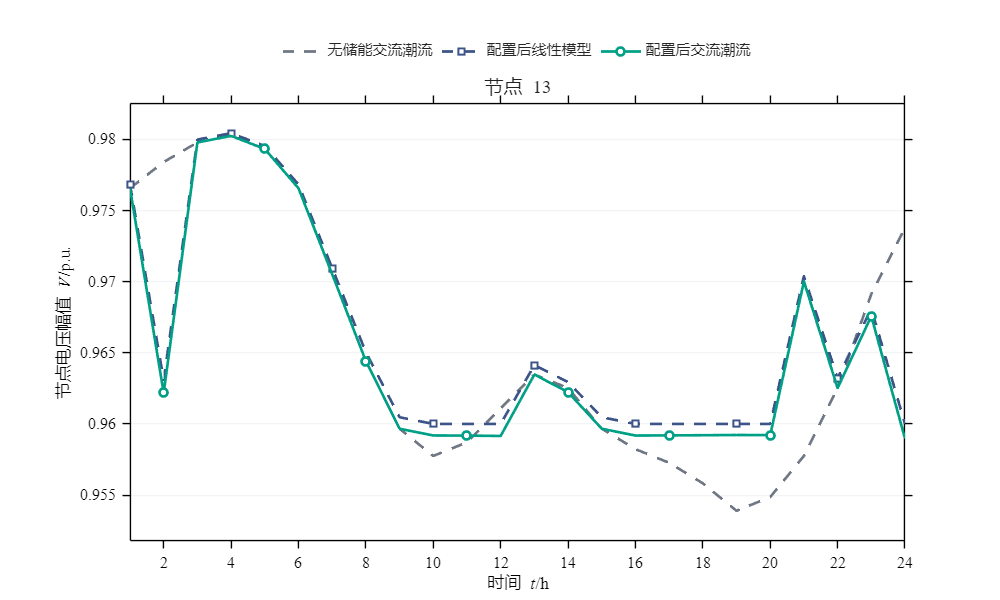

view_node = 13;
view_node=min(view_node,N_bus);
fig_planning=ess_live_view('planning',V_ac_base,V_lin_pu,V_ac_ess,view_node);

## 保存本次教学结果

文件写入 interactive/results 下本学号的目录。结果结构体沿用课程六个字段；不覆盖作业示例中的结果。

out_dir=fullfile(lesson.results,sprintf('Lesson04_%d',Stu_ID));
if ~isfolder(out_dir),mkdir(out_dir);end
Result.StuID=Stu_ID;Result.Obj_Value=value(Objective);
Result.Opt_Sites=find(round(value(z))==1);
Result.Opt_P_rated=value(P_rated);Result.Opt_E_rated=value(E_rated);
Result.Max_V_Err=max_voltage_error_pu;
save(fullfile(out_dir,'result_summary.mat'),'Result');
if export_figures
 ess_live_export(fig_bigm,out_dir,'BigM_Explorer');
 ess_live_export(fig_planning,out_dir,'Planning_Voltage');
end

Lesson_Stats=struct('Lesson',4,'AnnualCost_Yuan',value(Objective),'MinACVoltage',AC_MinVoltage,'MaxACVoltage',AC_MaxVoltage,'MaxVoltageError',max_voltage_error_pu,'LossBenefit_Yuan',B_loss_ann);

## 练习与报告分析

提高单位能量投资费用或线性模型电压下限。记录配置、年综合费用和交流最低电压，说明哪些约束影响了配置选择。报告同时给出参数、模型、运行曲线及结果解释。